%  Разбор данных
% запись путей
addpath(genpath('E:\Motorcycle\Models\MatLab'))

% Прописываем пути к данным
PathsDan=struct('Work', 'E:\Motorcycle\Data\MatLab', ...
                'WorkModuls', 'E:\Motorcycle\Models\MatLab', ...
                'Home', 'E:\Motorcycle\Data\MatLab', ...
                'HomeModuls', 'E:\Motorcycle\Models\MatLab');
PathsDan.Work

ans = 'E:\Motorcycle\Data\MatLab'

cd(PathsDan.WorkModuls)

addpath(genpath(PathsDan.Home))


danfiles=cell(1);
danfiles{1}="20210930_1_50kg_200kmh"; % 1
danfiles{2}="T1_2021-10-06";          % 2
danfiles{3}="T1_2021-10-06_2";        % 3
danfiles{4}="T3_2021-10-08_10-33";    % 4
danfiles{5}="T4_2021-10-08_10-36";    % 5
danfiles{6}="T5_2021-10-08_10-44";    % 6  трамплин
danfiles{7}="T6_2021-10-08_11-28";     % 7  


%load('-mat', 'E:\MotoDan\mU\T1_2021-10-06')

%T1Load = LoadDan(PathsDan.Work, danfiles(2));
%T2Load = LoadDan(PathsDan.Work, danfiles(3));
%T = LoadDan(PathsDan.Work, danfiles{7});

mfilter = MFilter();


% Тест данных
verMatlab = 2017;
basaTitle = "T4 povorot long ";
SetParamFFT = struct('step', 1, 'nfft', 64, 'limit', 32);  
SetParamInfo = struct('Title', basaTitle, 'Ver', verMatlab);  
SetPathX = struct('Dir', PathsDan.Work, 'Files', danfiles{4})

SetPathX = struct with fields:
      Dir: 'E:\Motorcycle\Data\MatLab'
    Files: "T3_2021-10-08_10-33"



testDan1 = AnalysisDan1(SetPathX, SetParamInfo);

pathfile = "E:\Motorcycle\Data\MatLab\T3_2021-10-08_10-33.mat"

PitchVel
RollVel
YawVel
YawAcc
XYZ.X
XYZ.Y
XYZ.Z


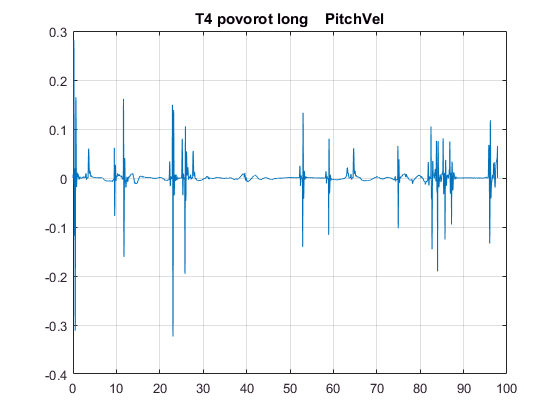

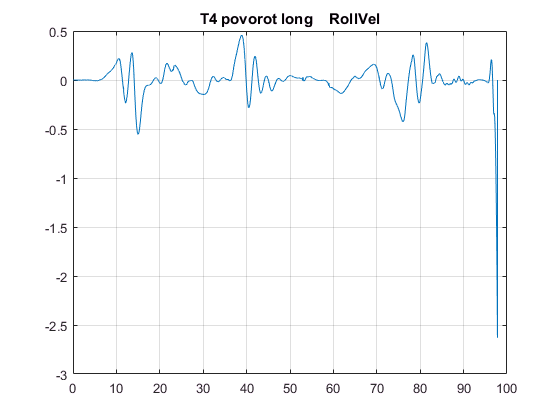

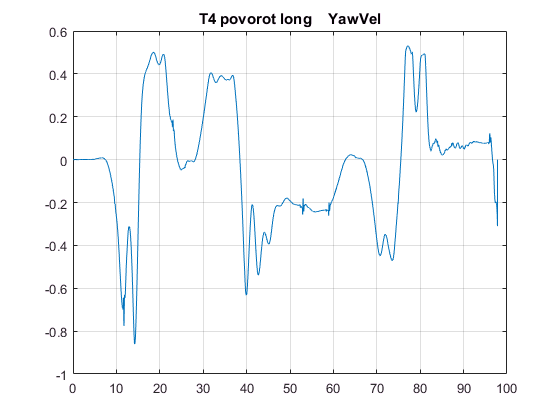

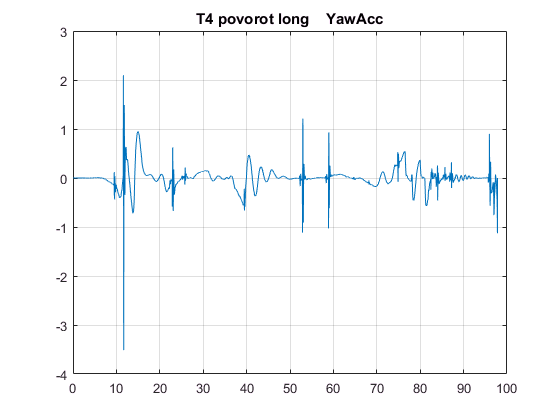

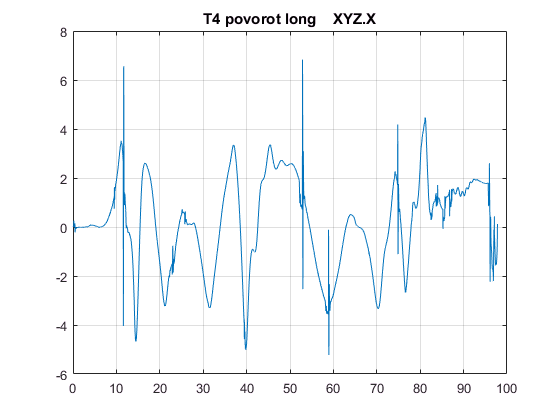

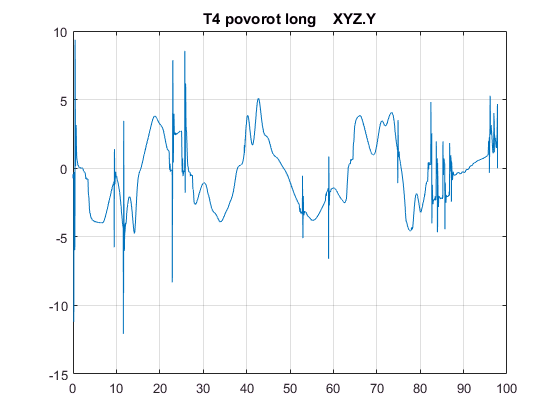

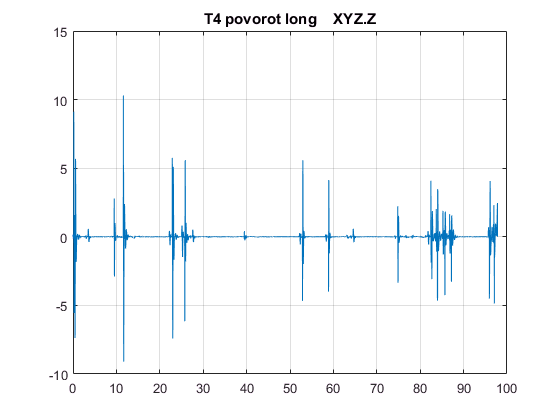

testDan1.PlotXnames(["PitchVel", "RollVel", "YawVel", "YawAcc", "XYZ.X", "XYZ.Y", "XYZ.Z"]);

  -- spectrum  from data:
PitchVel
RollVel
YawVel
YawAcc
XYZ.X
XYZ.Y
XYZ.Z


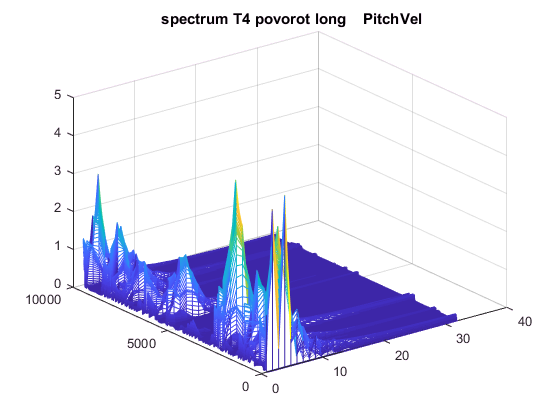

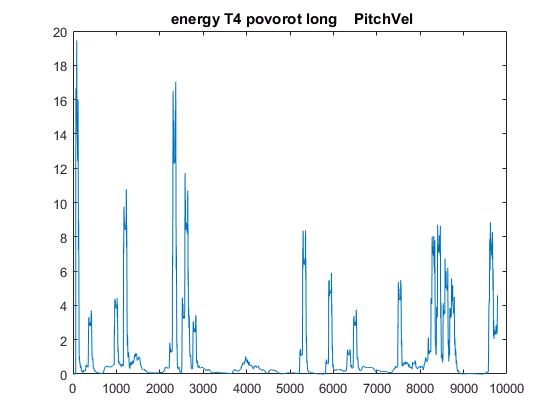

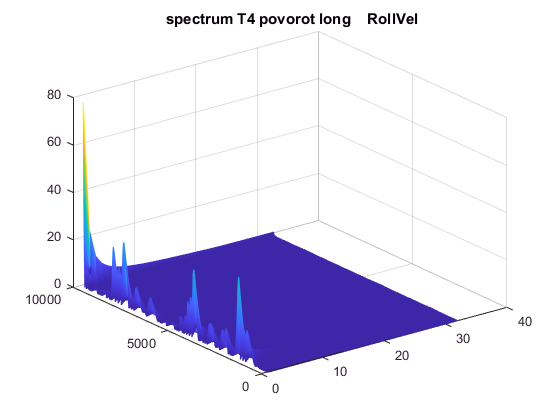

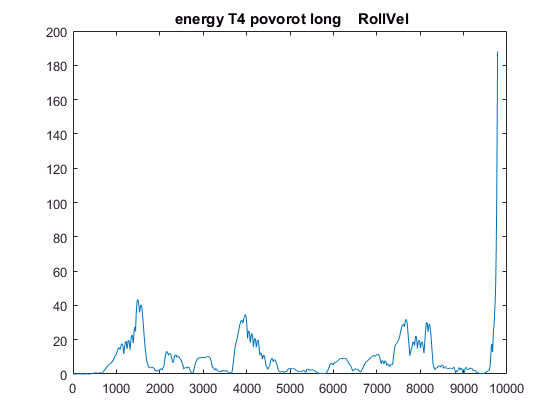

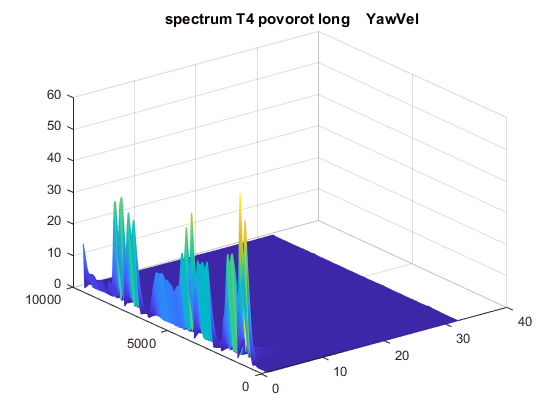

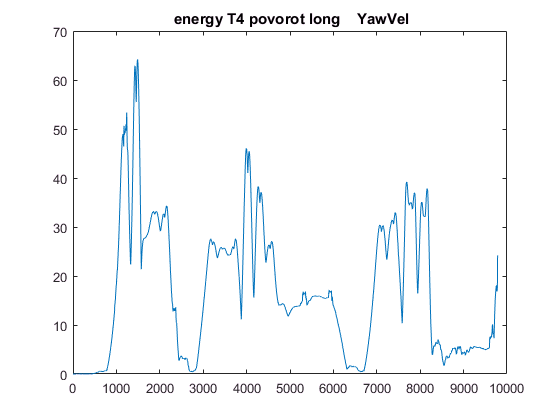

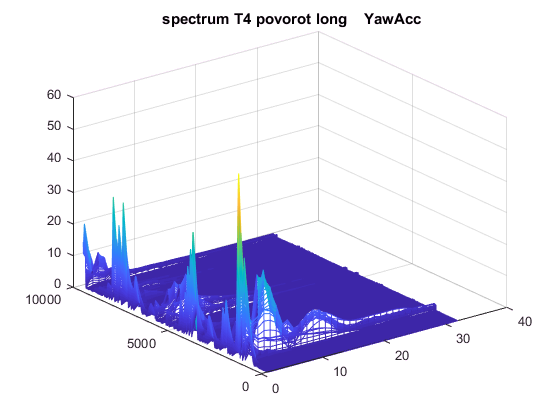

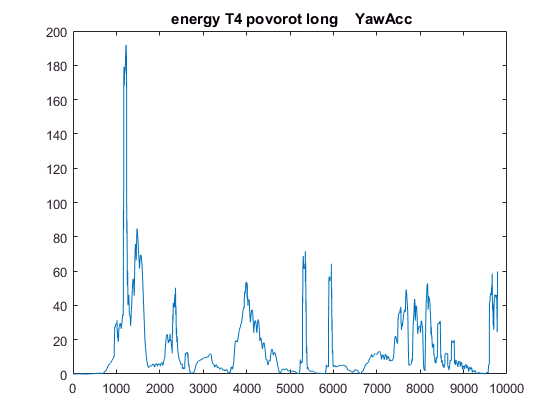

zout=testDan1.Spectrum(["PitchVel", "RollVel", "YawVel", "YawAcc", "XYZ.X", "XYZ.Y", "XYZ.Z"], SetParamFFT);

%testDan1.PlotXnames(["PitchVel", "RollVel", "YawVel", "YawAcc", "XYZ.X", "XYZ.Y", "XYZ.Z"]);
%zout=testDan1.Spectrum(["PitchVel", "RollVel", "YawVel", "YawAcc", "XYZ.X", "XYZ.Y", "XYZ.Z"], SetParamFFT);

%testDan1.PlotXYZg(["PitchVel", "RollVel", "YawVel", "YawAcc"])
%testDan.PlotXYZ()
% testDan1.vBelt();
% proskal = testDan1.Proskal();
%testDan1.PlotXnames(["PitchVel","YawVel", "YawAcc", "Engine.Trq", "Engine.Rotv", "XYZ.X", "XYZ.Y", "XYZ.Z"]);
% zout=testDan1.Spectrum(["YawVel", "YawAcc", "XYZ.X", "XYZ.Y", "XYZ.Z"], SetParamFFT);
% testDan1.PlotXnames(["Frc.X", "Frc.Z", "muRoad.R"]);
% testDan1.mU();      


mnogMatr = [0,0,0,0,1,1,1,1,1,1,1,1,1,1,1,1,1,1,1,1,1,1,1,1,0,0,0,0,0,0,0,0,0,0,0,0,0,0,0,0,0,0,0,0,0,0,0,0,0,0,0,0,0,0,0,0,0,0,0,0,0,0,0,0];
%tYawAcc = formX(testDan1.Dan.XYZg.YawAcc);
tTest = formX(testDan1.Dan.XYZg.YawAcc);



%  "YawVel"
YawVel =testDan1.Dan.Get("YawVel");

YawVel


Time


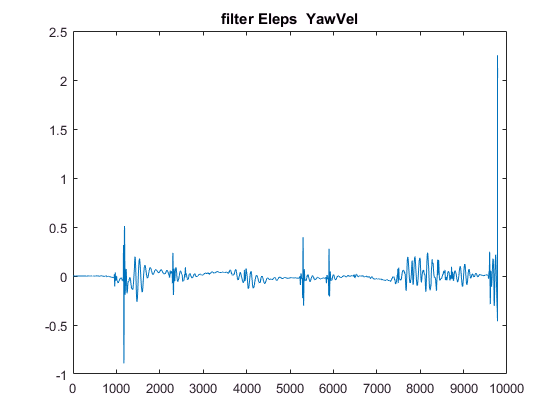

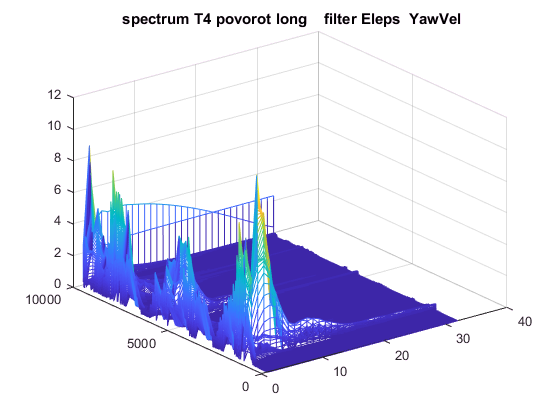

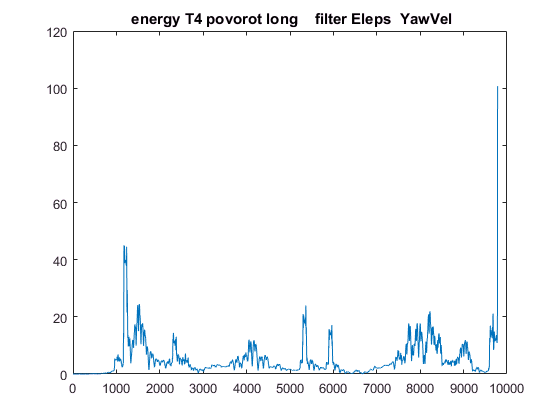

filtrYawVel = FNChEleps(YawVel)*10;
testDan1.FiltrSpectrumBasa(testDan1.Dan.Get("Time"), filtrYawVel, "filter Eleps  YawVel");

%  "XYZ.Y"
XYZY =testDan1.Dan.Get("XYZ.Y");

XYZ.Y


Time


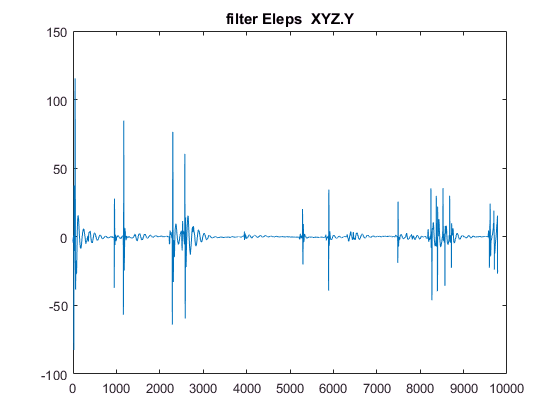

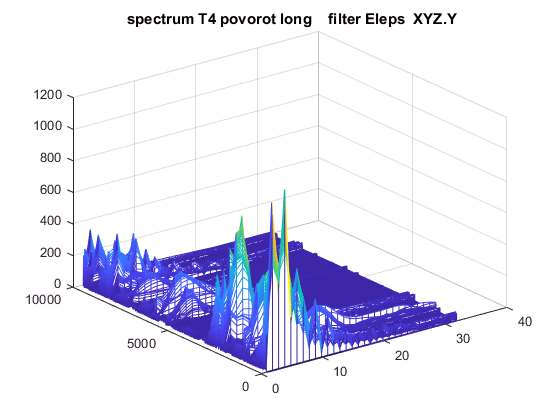

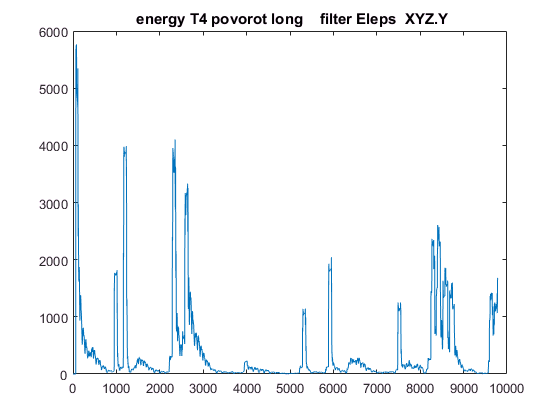

filtrYawVel = FNChEleps(XYZY)*10;
testDan1.FiltrSpectrumBasa(testDan1.Dan.Get("Time"), filtrYawVel, "filter Eleps  XYZ.Y");

RollVel


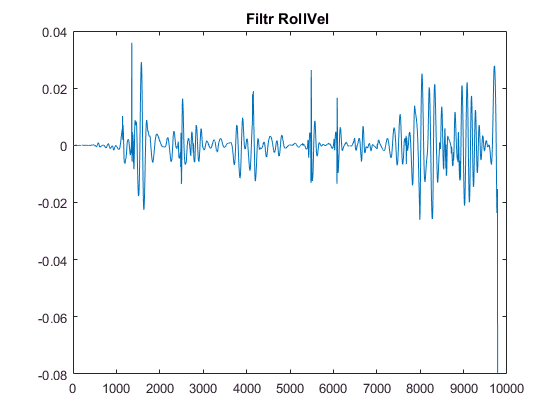

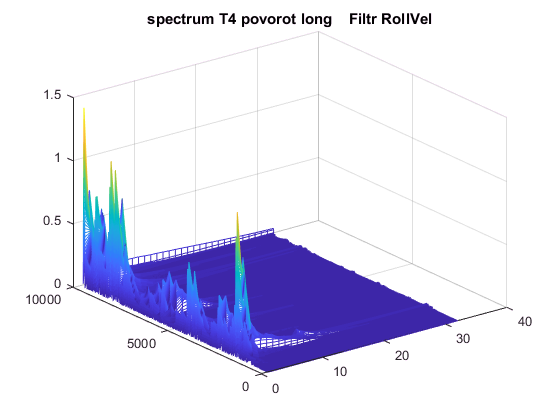

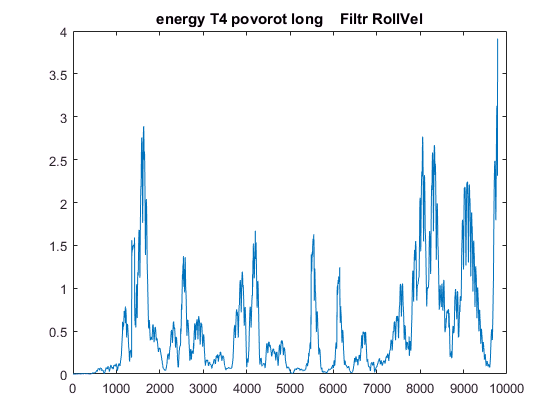

testDan1.FiltrSvchChebSpectrum("RollVel", "Filtr RollVel ");

Time
YawVel


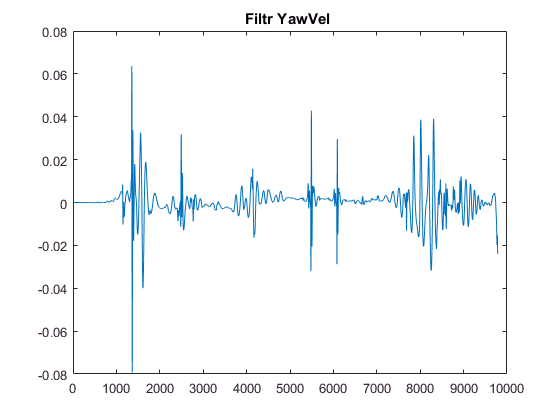

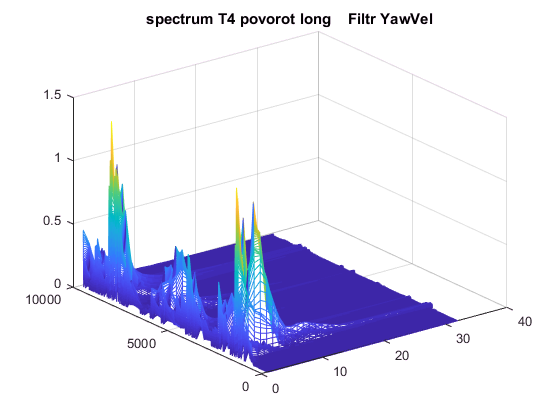

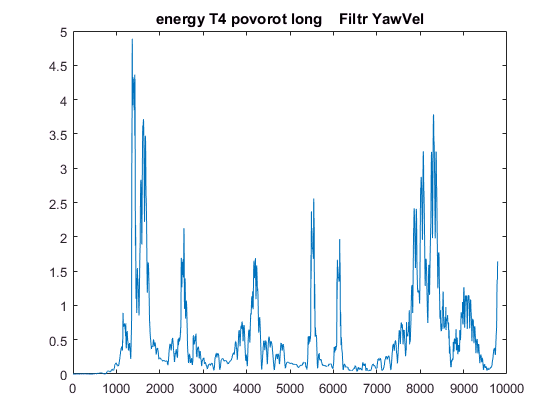

%zzz = mfilter.FSVCH_Cheb(testDan1.Dan.Get("YawVel"));

testDan1.FiltrSpectrumBasa(testDan1.Dan.Get("Time"), mfilter.FSVCH_Cheb(testDan1.Dan.Get("YawVel")), "Filtr YawVel ")

testDan1.PlotSignal2021("XYZ.Y")

XYZ.Y


Undefined function 'tiledlayout' for input arguments of type 'double'.

Error in Plot2021/PlotVertical (line 11)
            tiledlayout(n,m0)

Error in AnalysisDan1/PlotSignal2021 (line 159)
            obj.plot2021.PlotVertical(mm);

mm=cell(1,1);
nameSignal = "YawVel"
mm{1,1}=struct('mas', testDan1.Dan.Get(nameSignal), 'title', nameSignal);
nextFiltr =FNChEleps(testDan1.Dan.Get(nameSignal))*10;
mm{2,1}=struct('mas', nextFiltr, 'title', " - filtr "+nameSignal);
fftx = MyFFT01(testDan1.Dan.Time, nextFiltr, SetParamFFT);             
[e,z] = fftx.AllFFTe();   
mm{3,1}=struct('mas', z, 'title', " - spectr "+nameSignal);
mm{4,1}=struct('mas', e', 'title', " - energya spectra "+nameSignal);
testDan1.plot2021.PlotVertical(mm)

function d0 = formX(d)
    count = length(d);
    step = 0.01;
    d0(:,1)=0:step:(count-1)*step;
    d0(:,2)=d;
end
